syms H z n
n = [8 10 -6]; 
d = [1 2 -1 -2];
H = tf(n,d,0.1)


H =
 
   8 z^2 + 10 z - 6
  -------------------
  z^3 + 2 z^2 - z - 2
 
Sample time: 0.1 seconds
Discrete-time transfer function.



poles = pole(H)

poles =     1.0000
   -2.0000
   -1.0000


zeros = zero(H)

zeros =    -1.6930
    0.4430


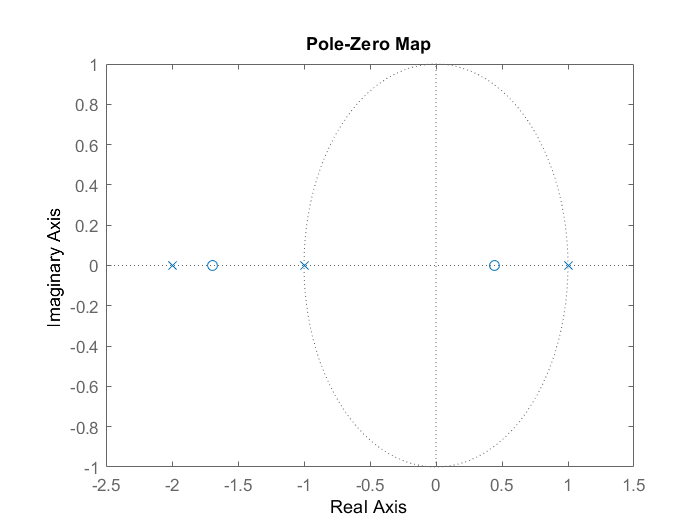

pzmap(H)

H_zp = 8*((z-zeros(1))*(z-zeros(2)))/((z-poles(1))*(z-poles(2))*(z-poles(3)))

$$H\_zp = \frac{8\,\left(z-\frac{3990193486702919}{9007199254740992}\right)\,\left(z+\frac{7624596277564579}{4503599627370496}\right)}{\left(z-1\right)\,\left(z+1\right)\,\left(z+2\right)}$$

[R,P,K] = residue(n,d)

R =     2.0000
    2.0000
    4.0000


P =    -2.0000
    1.0000
   -1.0000



K =

     []



H_res = R(1)/(z-P(1)) + R(2)/(z-P(2)) + R(3)/(z-P(3)) 

$$H\_res = \frac{2}{z-1}+\frac{4}{z+1}+\frac{2}{z+2}$$